### Repetição 3 a,b,c co n=16 

%dois componentes 1 e 2
p1 = 0.2/100 ;%prob defeito
p2 = 0.5/100 ;
p3 = 1/100;
N = 1e6;

 a)

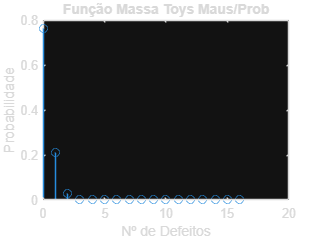

n = 16;
amostral = 0:n;
prob_tete = zeros(1, length(amostral));
index = 1; 
defeitos_array = zeros(1,n+1);
for i = 1:N
    defeitos = 1;    
    for j = 1:n    
        if rand < p1 || rand < p2 || rand < p3
            defeitos = defeitos + 1;
        end
    end
    defeitos_array(defeitos) = defeitos_array(defeitos)+1;
end
probabilidades = defeitos_array/N;

stem(0:n,probabilidades);
title('Função Massa Toys Maus/Prob');
xlabel('Nº de Defeitos');
ylabel('Probabilidade');

    b)

fprintf('A probabilidade de X >=2 = %.4f', sum(probabilidades(3:n+1)));

A probabilidade de X >=2 = 0.0293

c)

valor_esperado = sum(amostral .* probabilidades);
variancia = sum((amostral - valor_esperado).^2 .* probabilidades);
desvio_padrao = sqrt(variancia);
fprintf('O valor esperado é %.4f \nA variância é %.4f \nO desvio padrão é %.4f' ,valor_esperado, variancia, desvio_padrao)

O valor esperado é 0.2706 
A variância é 0.2659 
O desvio padrão é 0.5156